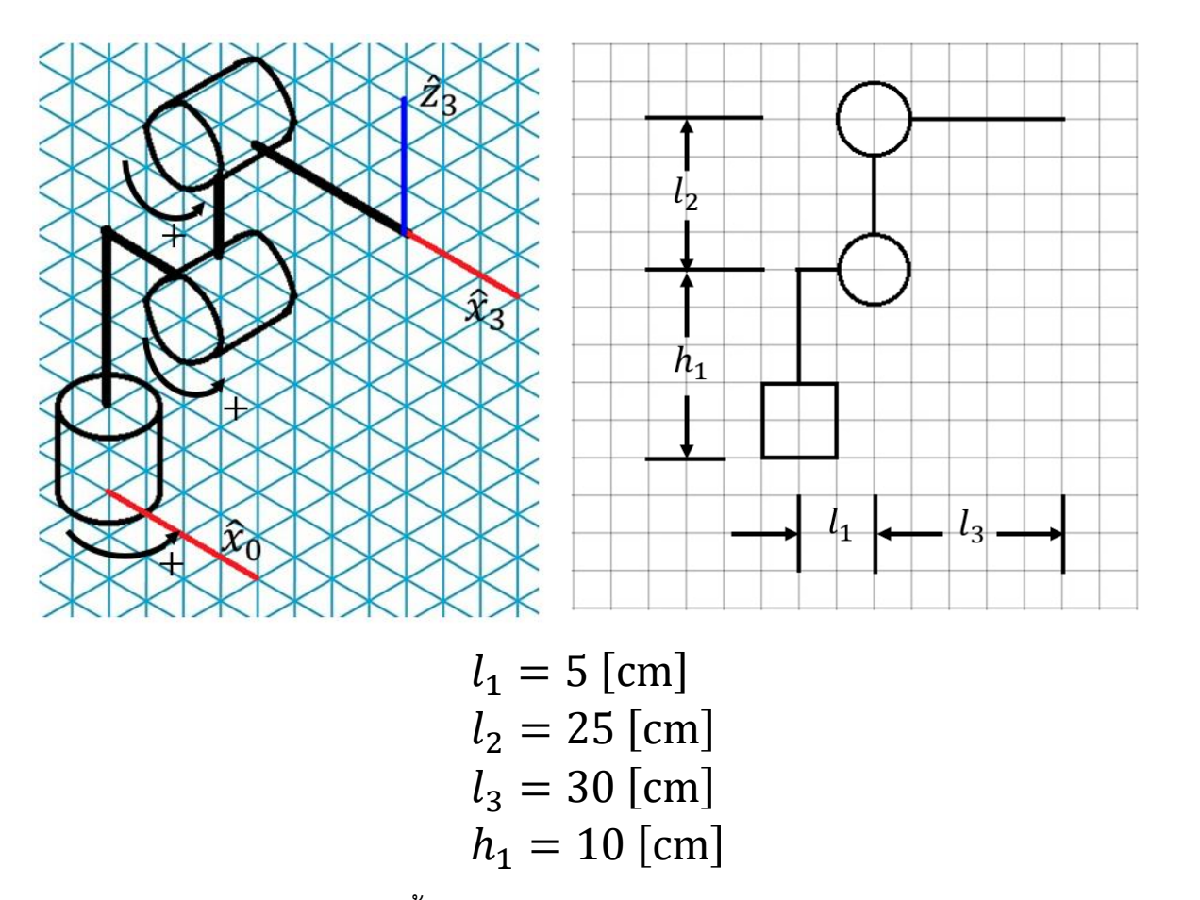                                                                                                                                                                                                                                

**input**

    .txt:    robot command = (2,n)

    .txt:    via_point_info = (3,m) // m = size of command via_points_task set in task space

**local variable**

    command = (1,n) L:0,J:1 

    via_point_task = (3,n) 

    via_point_joint_all = (3,n,4)

    via_point_joint = (3,n)

**step(function)**

readVariable => task2jointConversion =>  select optimal joint => gen C

**readVariable:** write .txt + return: via_point_task = (3,n), command = (1,n) L:0,J:1 

      Description: read variable

via_point_task ($\overrightarrow{\mathbf{P}}$)     : $\Re^{\mathrm{N}\times \mathrm{M}}$ which $\mathbf{N}$ is cartesian dimensions and $\mathbf{M}$ is number of via-point

command ($\overrightarrow{\mathbf{A}}$)            : $\overrightarrow{\mathbf{A}} \in {\left\lbrace 0,1\right\rbrace }^{1\times \mathrm{M}}$ which $\mathbf{M}$ is number of via-point ("**0**" means mode L operation and "**1**" means mode J operation)


$$\overrightarrow{\mathbf{P}} =\left\lbrack \begin{array}{cccc}
\overrightarrow{p_1 }  & \overrightarrow{p_2 }  & \overrightarrow{p_3 }  & \cdots 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
p_{x_1 }  & p_{x_2 }  & p_{x_3 }  & \cdots \\
p_{y_1 }  & p_{y_2 }  & p_{y_3 }  & \cdots \\
p_{z_1 }  & p_{z_2 }  & p_{z_3 }  & \cdots 
\end{array}\right\rbrack$$


[command, via_point_task] = readVariable("robot_command_modeJ.txt", "via_points_info.txt")

command =      1     1     1     1     1     1


via_point_task =     0.3500    0.3500    0.3500    0.3500    0.3500    0.3500
         0         0    0.3500   -0.3500         0         0
    0.3500    0.1000    0.3500    0.3500    0.1000    0.3500


**task2jointConversion:** return alert 0: cant access, 1: accessable; via_point_joint (3x4xn) D2: possible joint, D3: No. input via_point task

      Description: check possible access + convert task to joint

via_point_joint       : $\Re^{\mathrm{K}\times \mathrm{S}\times \mathrm{M}}$ which $\mathbf{K}$ is number of joint, $\mathbf{S}$ is number of robot pose and $\mathbf{M}$ is number of via-point

[alert, via_point_joint] = task2jointConversion(via_point_task_all);
via_point_joint

via_point_joint = via_point_joint(:,:,1) =

         0         0         0         0
   -1.7521         0   -1.7521         0
    3.1416         0    3.1416         0


via_point_joint(:,:,2) =

         0         0         0         0
   -2.7118   -0.4298   -2.7118   -0.4298
   -2.7118   -0.4298   -2.7118   -0.4298


via_point_joint(:,:,3) =

    0.7854    0.7854    0.7854    0.7854
   -1.4791   -0.6388   -1.4791   -0.6388
    2.3378    0.8038    2.3378    0.8038


via_point_joint(:,:,4) =

   -0.7854   -0.7854   -0.7854   -0.7854
   -1.4791   -0.6388   -1.4791   -0.6388
    2.3378    0.8038    2.3378    0.8038


via_point_joint(:,:,5) =

         0         0         0         0
   -2.7118   -0.4298   -2.7118   -0.4298
   -2.7118   -0.4298   -2.7118   -0.4298


via_point_joint(:,:,6) =

         0         0         0         0
   -1.7521         0   -1.7521         0
    3.1416         0    3.1416         0


**optimalPath: **return selected_via_point_joint (3xn)

      Description: select the robot pose that took shortest path cost

selected_via_point_joint ($\overrightarrow{\mathbf{Q}}$)    : $\Re^{\mathrm{K}\times \mathrm{M}}$ which $\mathbf{K}$ is number of joint and $\mathbf{M}$ is number of via-point


$$\overrightarrow{\mathbf{Q}} =\left\lbrack \begin{array}{cccc}
\overrightarrow{q_1 }  & \overrightarrow{q_2 }  & \overrightarrow{q_3 }  & \cdots 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
q_{1_1 }  & q_{1_2 }  & q_{1_3 }  & \cdots \\
q_{2_1 }  & q_{2_2 }  & q_{2_3 }  & \cdots \\
q_{3_1 }  & q_{3_2 }  & q_{3_3 }  & \cdots 
\end{array}\right\rbrack$$


[selected_via_point_joint, all_via_point_joint, cost] = optimalPath(via_point_joint, "shortest_path");

min_cost = 4.8976

min_idx = 1365

selected_via_point_joint

selected_via_point_joint =          0         0    0.7854   -0.7854         0         0
         0   -0.4298   -0.6388   -0.6388   -0.4298         0
         0   -0.4298    0.8038    0.8038   -0.4298         0


**coefficientGen: **return set of C, t_i, and tau

      Description: return for quintic polynomial coefficients and via-point time stamp (in configuration space)

$\overrightarrow{\mathbf{C}}$    : $\Re^{\mathrm{N}\times \mathrm{U}\times \left(\mathrm{M}-1\right)}$ which $\mathbf{N}$ is cartesian dimensions, $\mathbf{U}$ is quintic polynomial coefficients and $\mathbf{M}$ is number of via-point


$$\overrightarrow{\mathbf{C}} =\left\lbrack \begin{array}{cccccc}
{\overrightarrow{{\mathit{\mathbf{c}}}_0 } }_{\textrm{q1}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_1 } }_{\textrm{q1}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_2 } }_{\textrm{q1}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_3 } }_{\textrm{q1}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_4 } }_{\textrm{q1}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_5 } }_{\textrm{q1}} \\
{\overrightarrow{{\mathit{\mathbf{c}}}_0 } }_{\textrm{q2}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_1 } }_{\textrm{q2}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_2 } }_{\textrm{q2}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_3 } }_{\textrm{q2}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_4 } }_{\textrm{q2}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_5 } }_{\textrm{q2}} \\
{\overrightarrow{{\mathit{\mathbf{c}}}_0 } }_{\textrm{q3}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_1 } }_{\textrm{q3}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_2 } }_{\textrm{q3}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_3 } }_{\textrm{q3}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_4 } }_{\textrm{q3}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_5 } }_{\textrm{q3}} 
\end{array}\right\rbrack$$


$\overrightarrow{{\mathit{\mathbf{t}}}_i }$(via-point time stamp)    : $\Re^{1\times \left(\mathrm{M}-1\right)}$ which $\mathbf{M}$ is number of via-point

%Setting maximum velocity and acceleration of each joint
v_max = 1.75;
a_max = 0.5;

[C,t_i,T,alert_traj] = coefficientGen(selected_via_point_joint, v_max, a_max)

C = C(:,:,1) =

         0         0         0         0         0         0
         0         0         0   -0.3888    0.2618   -0.0470
         0         0         0   -0.3888    0.2618   -0.0470


C(:,:,2) =

         0         0         0    0.1461   -0.0581    0.0062
   -0.4298         0         0   -0.0389    0.0155   -0.0016
   -0.4298         0         0    0.2295   -0.0912    0.0097


C(:,:,3) =

    0.7854         0         0   -0.2033    0.0716   -0.0067
   -0.6388         0         0         0         0         0
    0.8038         0         0         0         0         0


C(:,:,4) =

   -0.7854         0         0    0.1461   -0.0581    0.0062
   -0.6388         0         0    0.0389   -0.0155    0.0016
    0.8038         0         0   -0.2295    0.0912   -0.0097


C(:,:,5) =

         0         0         0         0         0         0
   -0.4298         0         0    0.3888   -0.2618    0.0470
   -0.4298         0         0    0.3888   -0.2618    0.0470


t_i =          0    2.2277    6.0019   10.2607   14.0349


T = 16.2626

alert_traj = 0

**polyTrajEval: **return set of p1, v1, a1

      Description: return the position, velocity and acceleration in configuration space

sampling = 1e-2; t = (0:sampling:T); %linspace(0,T,100+1);
p1 = [];
v1 = [];
a1 = [];

for i = 1:numel(t)
    k = discretize(t(i),[t_i T]);
   [p_j,v_j,a_j] = polyTrajEval(t(i),C(:,:,k),t_i(k));

    p1 = [p1 p_j];
    v1 = [v1 v_j];
    a1 = [a1 a_j];

end

[R,P,R_e,p_e] = forwardKine(p1);

p2 = p_e

p2 =     0.3500    0.3500    0.3500    0.3500    0.3500    0.3500    0.3500    0.3500    0.3500    0.3501    0.3501    0.3501    0.3502    0.3502    0.3502    0.3503    0.3504    0.3504    0.3505    0.3506    0.3507    0.3508    0.3509    0.3510    0.3511    0.3513    0.3514    0.3516    0.3517    0.3519    0.3521    0.3523    0.3525    0.3527    0.3529    0.3531    0.3534    0.3536    0.3539    0.3542    0.3545    0.3547    0.3550    0.3554    0.3557    0.3560    0.3563    0.3567    0.3570    0.3574
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

v2 = [zeros(3,1) diff(p2')']

v2 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

a2 = [zeros(3,1) diff(v2')']

a2 = 	1.0e+-4 *

         0    0.0010    0.0057    0.0113    0.0168    0.0221    0.0272    0.0322    0.0370    0.0416    0.0461    0.0505    0.0546    0.0586    0.0624    0.0661    0.0696    0.0728    0.0760    0.0789    0.0816    0.0842    0.0865    0.0887    0.0906    0.0924    0.0939    0.0953    0.0964    0.0974    0.0981    0.0987    0.0990    0.0991    0.0990    0.0987    0.0982    0.0975    0.0966    0.0955    0.0941    0.0926    0.0909    0.0890    0.0869    0.0847    0.0822    0.0796    0.0767    0.0738
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

**plotTrajectory: **void

      Description: visualization the plot of position, velocity and acceleration with respect to time in configuration and task space

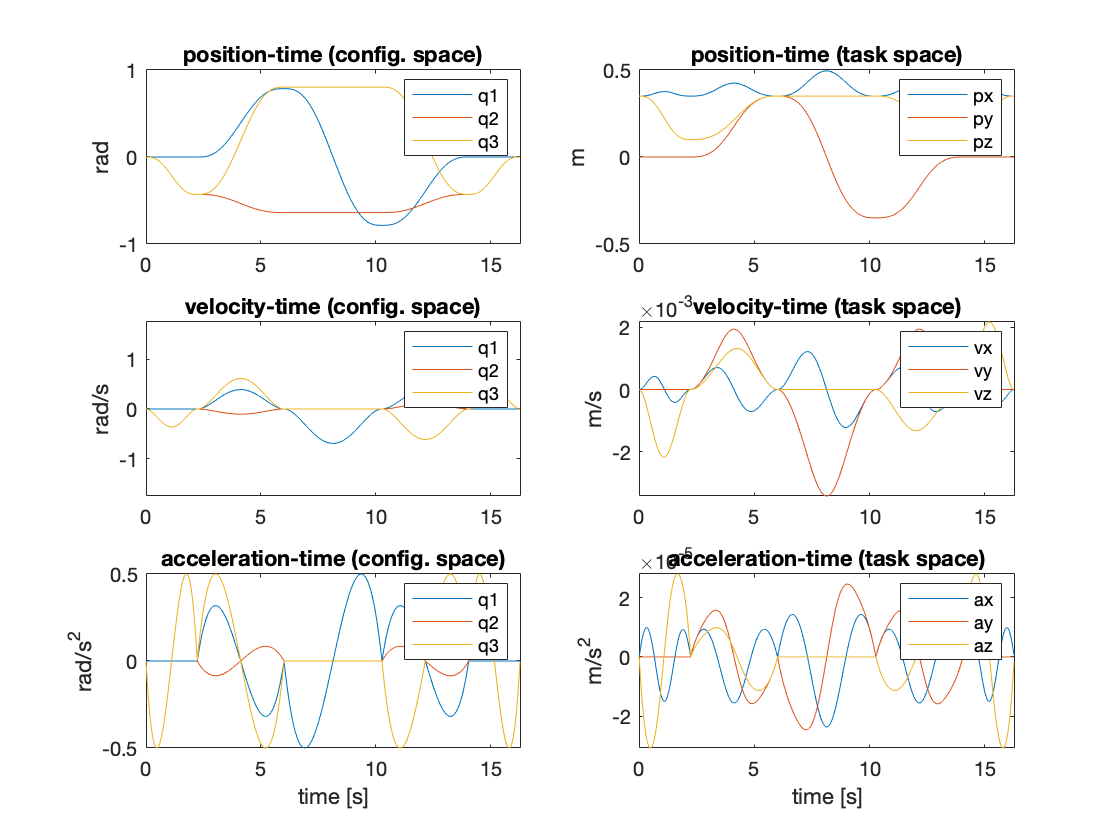

plotTrajectory(t, p1,v1,a1, p2,v2,a2, T, v_max,a_max)

**checkSingularity: **return alert_singularity, idx, border and J_v

[alert_singularity, idx, border,J_v] = checkSingularity(p1, t);
alert_singularity

alert_singularity = 0